EGB_st.name='EGB'; 
EGB_st.lat=44.231006;
EGB_st.lon=-79.783839;
EGB_st.alt=255;
EGB_st.env='con';
EGB_st.footp='RB';


EGB_rd2=read_betsy('egb_2009_2017',EGB_st.name);
EGB_rd=read_betsy('egb_2009_2018',EGB_st.name);

datevec(EGB_rd.Time(1))

ans =         2009          10          14           0           0           0


datevec(EGB_rd.Time(end))

ans =         2018           1           1           0           0           0


prctile(EGB_rd.U_S11,[5 50 95])

ans =     5.8050   23.1500   60.0000


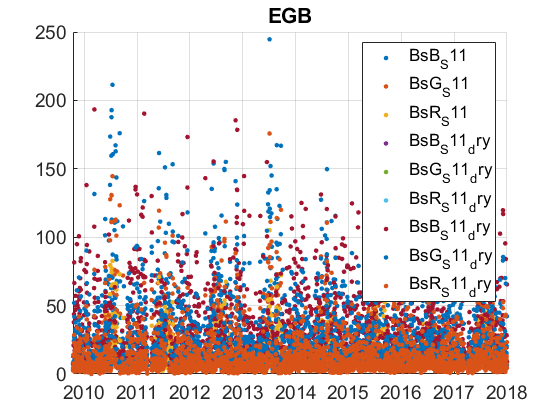

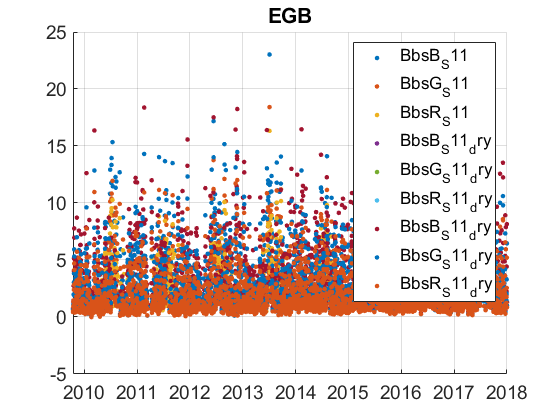

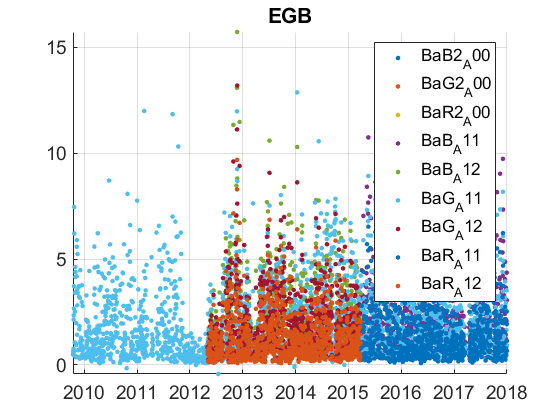

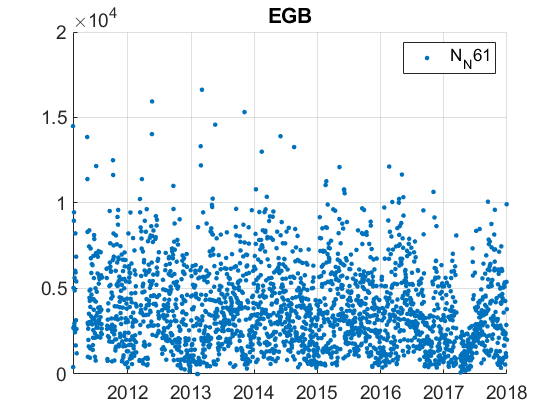

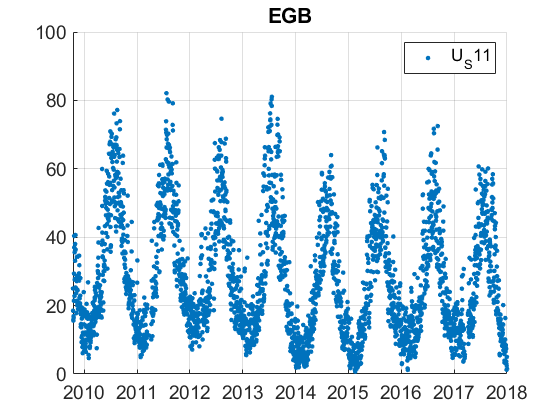

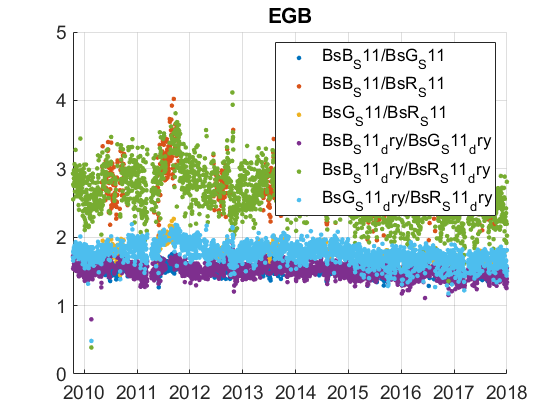

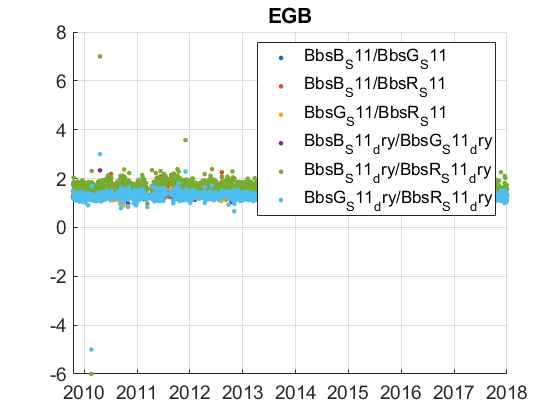

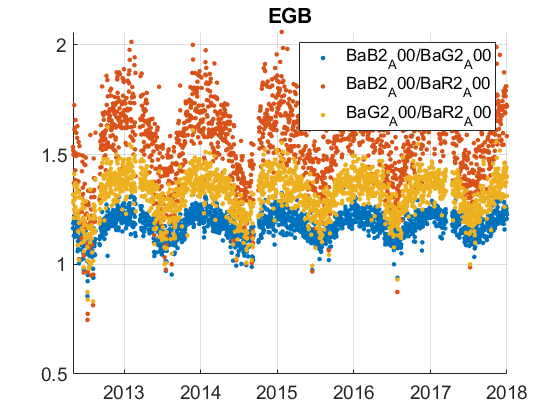


plotFigControl(EGB_rd,EGB_st.name);

% 1 size cut, ok
% sc: ok, no negatives,no clear seasonal cycle
%abs: no clear seasonality
%abs exp: clear seaonal cycle with max in winter

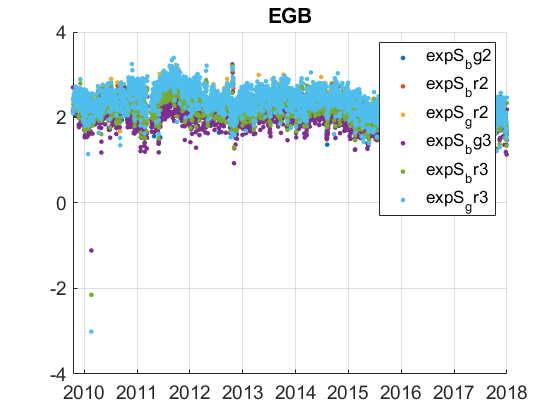

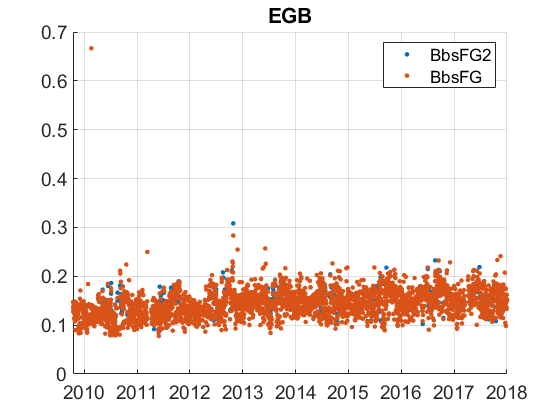

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
lambdaAE7=[370 470 520 590 660 880 950];
%EGB_cal=compute_exp_SSA(EGB_rd,lambdaSC, lambdaAE);
plotFigControl_cal(EGB_cal, EGB_st.name);

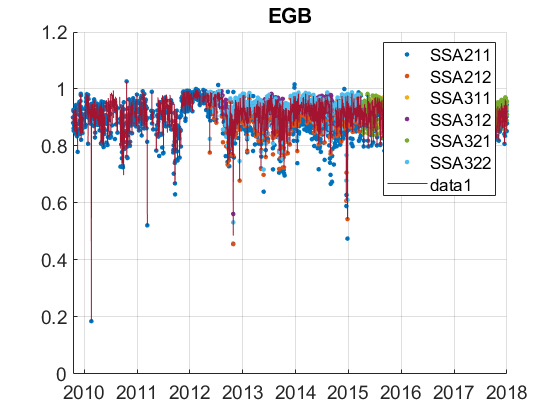


EGB_cal.SSA_G=EGB_rd.BsG_S11./(EGB_rd.BsG_S11+EGB_rd.BaG_A00);
hold on;
plot(EGB_rd.Time, EGB_cal.SSA_G);

%Questions:
%problems:

%scat: all the exponents seems to have a clear rupture at the end of 2014/beginning of 2015: do you have any explanation ?

%abs: from the beginning of 2014, Both PSAP and CLAP minima seems to be higher. Did you made any changes at the end of 2013 or the beginning of 2014 ?
%abs: at the end of 2011 and the beginning of 2012 the PSAP data are much lower than usual. Was the 1w PSAP working with problem at the end of his life? Should we invalidate these data ?

%N: there is much lower values from March to June 2017: What is the reason?

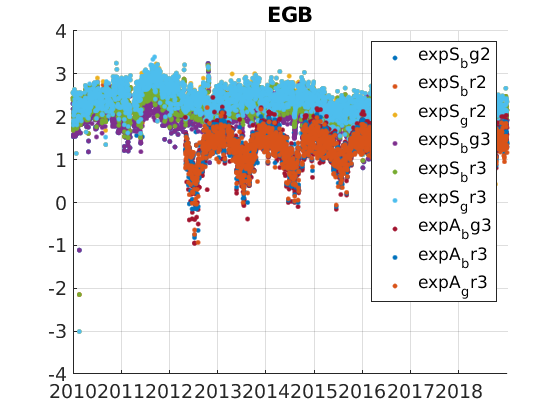

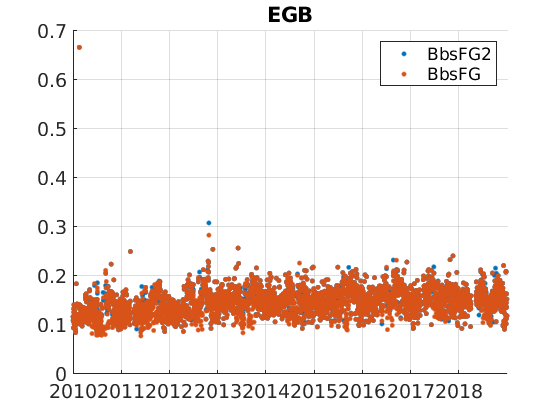

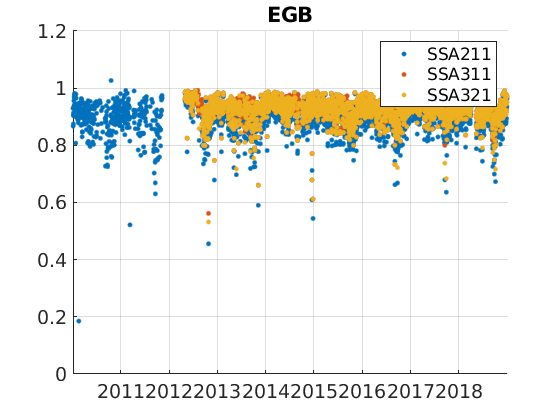

EGB_tr=EGB_rd;
EGB_tr.y=year(EGB_tr.Time);
%enleve une valeur de 2018
EGB_tr=EGB_tr(1:end-1,:);
% begin at the beginning of a year: 2010
%end: 2017--> only 8 y of measurements: too short for trend
P=timerange('2010-01-01','2019-01-01');
EGB_tr=EGB_tr(P,:);
%trend on U0_S11 has to be done: not constant U
%dry to use : also calculate exponent on dry if it is used
%AE31 not used: delete A81, only CAPS not used: deleter A12
%decide to use the time series with the max of CAPS (A00) due to better SSA: delete A11
names=fieldnames(EGB_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_";"U1";"N"]) | endsWith(names,["T";"A81";"A12";"A11"]);
N=names(c);
for i=1:length(N)
    EGB_tr.(N{i})=[];
end
names=fieldnames(EGB_tr);

%PSAP 1w to 3w in April 2012: problem end of 1w PSAP
%data to invalidate form 11.11.2011 to 1.05.2012
p1=timerange('2011-11-11','2012-05-01');
EGB_tr.BaB_A00(p1)=NaN;
EGB_tr.BaG_A00(p1)=NaN;
EGB_tr.BaR_A00(p1)=NaN;

 EGB_cal2=compute_exp_SSA(EGB_tr,lambdaSC, lambdaAE);
EGB_tr=outerjoin(EGB_tr,EGB_cal2);

 plotFigControl_cal(EGB_cal2, EGB_st.name);

 % compute trend only on g
EGB_tr.BaB_A00=[];
EGB_tr.BaR_A00=[];
EGB_tr.BsB_S11=[];
EGB_tr.BsR_S11=[];
EGB_tr.BsB_S11_dry=[];
EGB_tr.BsR_S11_dry=[];
EGB_tr.BbsB_S11=[];
EGB_tr.BbsR_S11=[];
EGB_tr.BbsB_S11_dry=[];
EGB_tr.BbsR_S11_dry=[];

%scat dry: less data in summer
% humidity lower since 2015 : exp has a rupture, 
%CALCULATE dry exponent S : it is also the same!

%abs exp: too short (2012:
% EGB_tr.expA_bg3=[];
% EGB_tr.expA_br3=[];
% EGB_tr.expA_gr3=[];

EGB_tr.expS_br2=[];
EGB_tr.expS_gr2=[];
EGB_tr.expS_br3=[];
EGB_tr.expS_gr3=[];
%SSA: make one time series with all the green data --> time serie since 2010
%SSA: end of PSAP 1w to invalidate
EGB_tr.SSAG_dry=EGB_tr.BsG_S11_dry./(EGB_tr.BsG_S11_dry+EGB_tr.BaG_A00);
EGB_tr.SSAG=EGB_tr.BsG_S11./(EGB_tr.BsG_S11+EGB_tr.BaG_A00);

EGB_result= all_trend_STN(EGB_tr,EGB_st); 

EGB_result_D=EGB_result;